# A simulation of a decoy BB84 link in fibre only

## 1. Choose parameters

wavelength=1550;                                                           %wavelength is measured in nm
time_gate_width=1E-9;                                                      %times are measured in s
spectral_filter_width=10;                                                  %consistent with wavelength, spectral width is measured in nm

## 2. Construct components

%2.1 source
source = components.Source(wavelength,...
                           'MPN_Signal',0.7,'MPN_Decoy',0.2,...
                           'Probability_Signal',0.75,'Probability_Decoy',0.2);
%2.2 transmitter
t = fibre.FibreNode('Source',source);

%2.3 detector
d = components.Detector(wavelength,source.repetition_rate,...
                        time_gate_width,spectral_filter_width,...
                        'Preset','QuantumOpus1550_CryogenicAmplifier');
%2.4 receiver
r = fibre.FibreNode('Detector',d);
%2.5 fibre
f = fibre.Fibre(1E5);%10km fibre

## 3 run

%3 run simulation
Result=fibre.qkdFibreSimulation(r,t,f,protocol.DecoyBB84);

## 4 Plot results

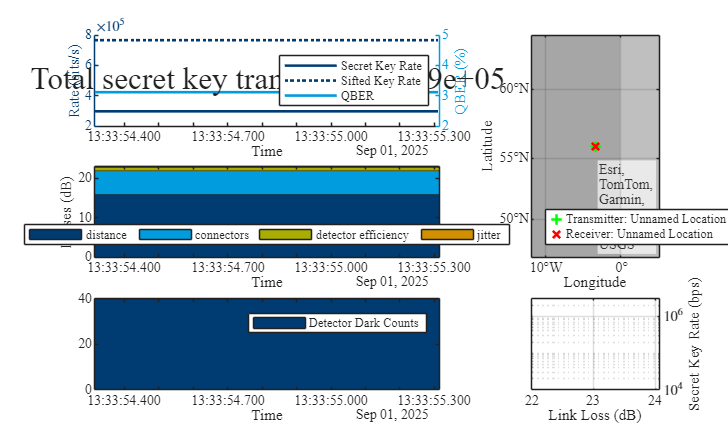

ans =   Figure (1: Decoy BB84 simulation from Unnamed Location to Unnamed Location) with properties:

      Number: 1
        Name: 'Decoy BB84 simulation from Unnamed Location to Unnamed Location'
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


%4 plot results
Result.plot()